data = load('flow_data.mat')

data = struct with fields:
      angles: [-12 0 12]
           c: 1540
     cmap_cf: [200×3 double]
     cmap_pd: [200×3 double]
          f0: 5208000
         prf: 3.0030e+03
          rf: [800×300×50×3 single]
    rf_bmode: [800×300 single]
           x: [-0.0120 -0.0119 -0.0118 -0.0118 -0.0117 -0.0116 -0.0115 -0.0114 -0.0114 -0.0113 -0.0112 -0.0111 -0.0110 -0.0110 -0.0109 -0.0108 -0.0107 -0.0106 -0.0106 -0.0105 -0.0104 -0.0103 -0.0102 -0.0102 -0.0101 -0.0100 -0.0099 … ] (1×300 double)
           z: [1.0000e-03 0.0010 0.0011 0.0011 0.0011 0.0012 0.0012 0.0012 0.0012 0.0013 0.0013 0.0013 0.0014 0.0014 0.0014 0.0015 0.0015 0.0015 0.0015 0.0016 0.0016 0.0016 0.0017 0.0017 0.0017 0.0018 0.0018 0.0018 0.0018 0.0019 0.0019 … ] (1×800 double)


## Part A.

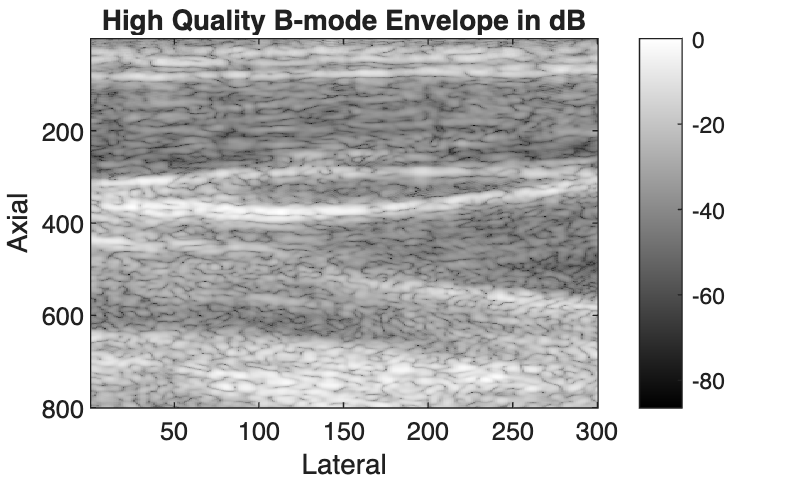

clf;

envh = abs(hilbert(rf_bmode));
envh_db = 20*log10(envh);
norm_envh = envh_db - max(envh_db(:));

figure()
imagesc(norm_envh);
colormap gray
colorbar;
title('High Quality B-mode Envelope in dB');
xlabel('Lateral');
ylabel('Axial');

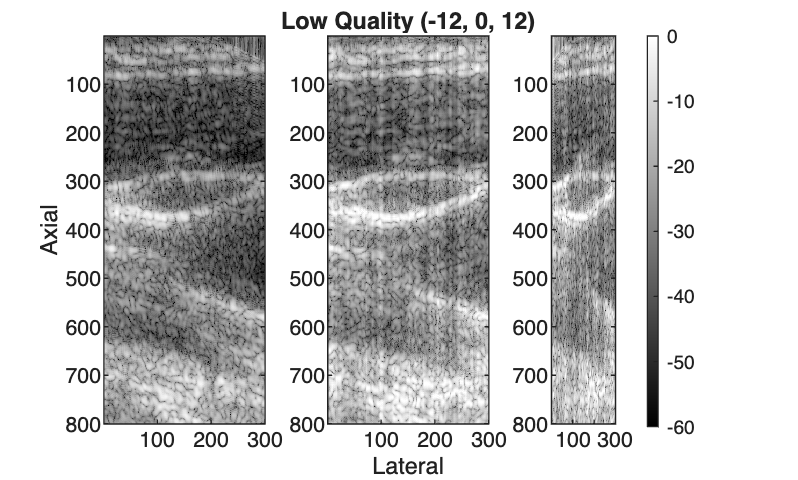


frame = 25;

envl1 = abs(hilbert(rf(:,:,frame,1)));
envl1_db = 20*log10(envl1);
norm_envl1 = envl1_db - max(envl1_db(:));

envl2 = abs(hilbert(rf(:,:,frame,2)));
envl2_db = 20*log10(envl2);
norm_envl2 = envl2_db - max(envl2_db);

envl3 = abs(hilbert(rf(:,:,frame,3)));
envl3_db = 20*log10(envl3);
norm_envl3 = envl3_db - max(envl3_db);

figure()
subplot(1,3,1)
imagesc(norm_envl1);
ylabel('Axial');
colormap gray;
clim([-60 0]);

subplot(1,3,2)
imagesc(norm_envl2);
title('Low Quality (-12, 0, 12)');
xlabel('Lateral');
colormap gray;
clim([-60 0]);

subplot(1,3,3)
imagesc(norm_envl3);
colormap gray;
colorbar;
clim([-60 0]);

## Part B. 

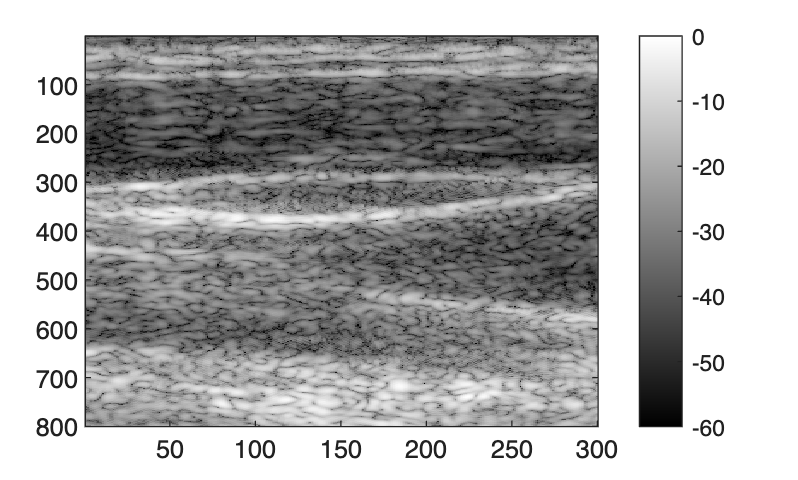


rf_12 = rf(:,:,:,2);

frames = 50;
M(frames) = struct('cdata', [], 'colormap', []);

vidfile = VideoWriter('b-mode.mp4','MPEG-4');
open(vidfile)
for i = 1:frames
    env = abs(hilbert(rf_12(:,:,i)));
    env_db = 20*log10(env);
    norm_env = env_db - max(env_db(:));
    
    imagesc(norm_env);
    colorbar;
    colormap gray;
    clim([-60 0]);

    drawnow limitrate;

    M(i) = getframe(gcf);
    writeVideo(vidfile, M(i));
end

close(vidfile);

## Part C.